% Setup
format compact
clearvars
clc
%hold off;

opts = spreadsheetImportOptions("NumVariables", 10);

% Specify sheet and range
opts.Sheet = "Motor  Tac. Pot. i ADC";
opts.DataRange = "A4:J30";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "VinMesurat", "Var4", "VinMitj", "Var6", "Var7", "Var8", "Var9", "VtacMesurat"];
opts.SelectedVariableNames = ["VinMesurat", "VtacMesurat"];
opts.VariableTypes = ["char", "char", "double", "char", "double", "char", "char", "char", "char", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var2", "Var4", "Var6", "Var7", "Var8", "Var9"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var4", "Var6", "Var7", "Var8", "Var9"], "EmptyFieldRule", "auto");

% Import the data
DadesenLlaobert = readtable("D:\TFG\Dades en Llaç obert.xlsx", opts, "UseExcel", false);

% Change data type
DadesenLlaobert = table2array(DadesenLlaobert);

% Clear temporary variables
clear opts

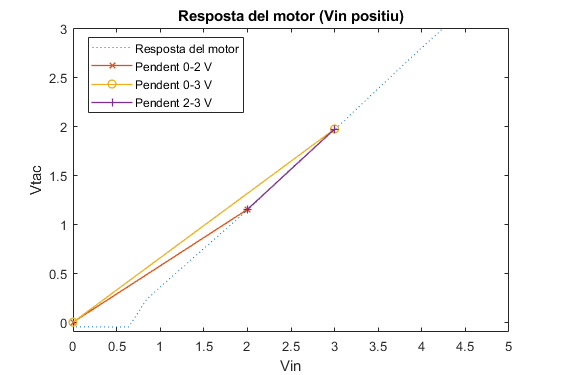

% Filtrem per al semieix positiu
indexPos = DadesenLlaobert(:,1) >= 0;
Vin(:) = DadesenLlaobert(indexPos,1);
Vtac(:) = DadesenLlaobert(indexPos,2);

plot(Vin, Vtac, ':')
hold on;
V2 = 1.15;
V3 = 1.97;
plot([0 2], [0 V2], 'x-', 'LineWidth',1)
plot([0 3], [0 V3], 'o-', 'LineWidth',1)
plot([2 3], [V2 V3], '+-', 'LineWidth',1)
axis([0 5 -0.1 3])
title('Resposta del motor (Vin positiu)')
xlabel('Vin')
ylabel('Vtac')
legend('Resposta del motor', 'Pendent 0-2 V', 'Pendent 0-3 V', 'Pendent 2-3 V')
legend("Position",[0.17,0.70,0.25,0.20])
hold off;
set(gcf,'units','pixels','position',[0,0,576,384]);
exportgraphics(gcf, '../Tests/Generats/CalculsK.png');